# Single Image Super Resolution w/ Learned NSOLT for RGB color image

Please do not forget to run** setpath **in the top directory of this package, and then return to this directory.

Requirements: 

- MATLAB R2021a

Acknowledgement:

- This work was supported by JSPS KAKENHI Grant Number JP19H04135.

 Contact address: Shogo MURAMATSU,

        Faculty of Engineering, Niigata University,

        8050 2-no-cho Ikarashi, Nishi-ku,

        Niigata, 950-2181, JAPAN

        [http://msiplab.eng.niigata-u.ac.jp](http://msiplab.eng.niigata-u.ac.jp)  

 Copyright (c) 2021, Shogo MURAMATSU, All rights reserved.

## Preparation

clear 
close all
support.fcn_download_img

lena.png already exists in ./data/
baboon.png already exists in ./data/
goldhill.png already exists in ./data/
barbara.png already exists in ./data/


### Original image

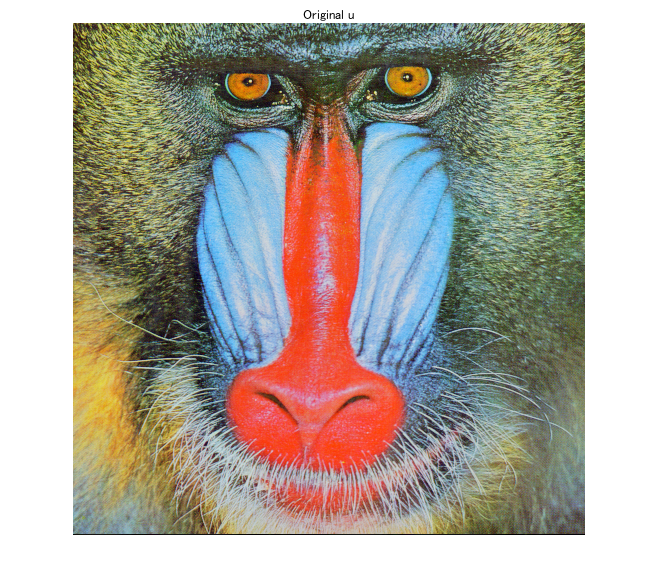

% Original image
%u = im2single(rgb2gray(imread('./data/baboon.png')));
u = im2single(imread('./data/baboon.png'));
figure(1)
imshow(u)
title('Original u')

### Observed image

Let us consider the single image super resolution problem of observation)

    
$$\mathbf{v}=\mathbf{Pu}+\mathbf{w}$$


which originates  $\mathbf{u}$ and is contaminated by additive white Gaussian noise $\mathbf{w}$ and downscale measurement proces, where $\mathbf{P}$ is a linear process consisting of low-pass filter and downsampling.

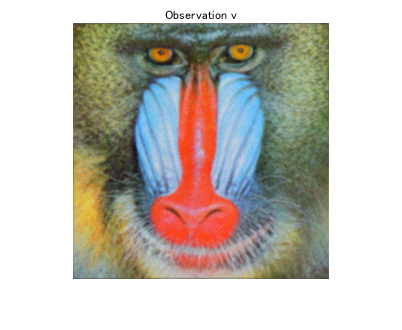

% Measurement process P
sigmah = 2;
h = fspecial('gaussian',9,sigmah);
downsample2 = @(x,m) ipermute(downsample(permute(downsample(x,m),[2 1 3]),m),[2 1 3]);
linproc = @(x) downsample2(imfilter(x,h,'conv','circ'),2);
H = fftn(h,2.^nextpow2([size(u,1) size(u,2)]));
beta = max(abs(H(:)).^2); % λmax(PP.')

% Observation
sigmaw = 5/255;
v = imnoise(linproc(u),'gaussian',0,sigmaw^2);
figure(2)
imshow(v)
title('Observation v');

## Bicubic interpolation

For the sake of reference, the result with the bicubic interpolation is shown.

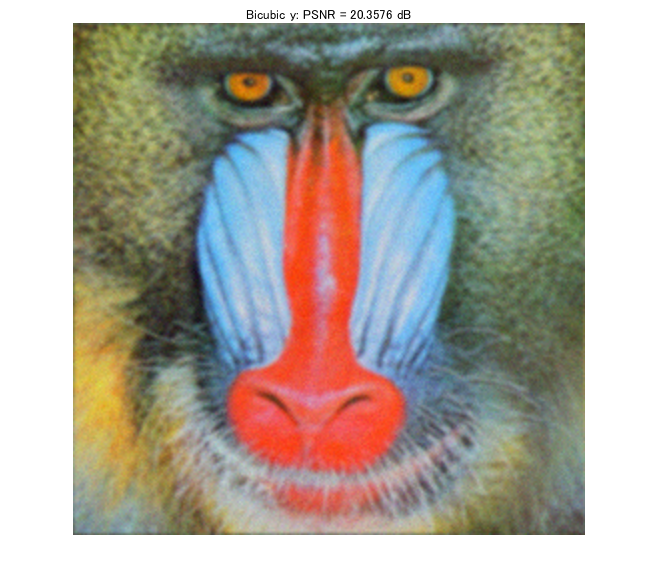

% Bicubic
y = imresize(v,2,'bicubic');
figure(3)
imshow(y)
title(['Bicubic y: PSNR = ' num2str(psnr(u,y)) ' dB']);

## Single image super resolution

The above denoising problem can be formulated by the  $\ell_1$-norm regularized least square problem with a redundant dictionary  $\mathbf{D}$  as

    $\hat{\mathbf{s}}=\arg\min_\mathbf{s}\frac{1}{2}\|\mathbf{v}-\mathbf{PDs}\|_2^2+\lambda\|\mathbf{s}\|_1$.

It is possible to obtain the solution by the proximal gradient algorithm

   
$$\mathbf{s}^{(t+1)}\leftarrow\mathrm{prox}_{\gamma\lambda\|\cdot\|_1}(\mathbf{s}^{(t)}-\gamma\nabla f(\mathbf{s}^{(t)}))$$


   
$$\nabla f(\mathbf{s})=\mathbf{D}^T\mathbf{P}^T(\mathbf{PDs}-\mathbf{v})$$


  $[\mathrm{prox}_{\gamma\lambda\|\cdot\|_1}(\mathbf{s})]_i=\mathcal{T}_{\gamma\lambda}([\mathbf{s}]_i)=\mathrm{sign}([\mathbf{s}]_i)\cdot\max(|[\mathbf{s}]_i|-\gamma\lambda,0)$,

where  $0<\gamma<2/\beta$ and $\beta$ is the Lipschitz constant of $\nabla f$.

In the following, let us perform single image super-resolution (SISR) with a proximal gradient method using the nonseparate oversampled laped transform (NSOLT) trained in Sample 13-4 as a dictionary.

Since  $\mathbf{DD}^T=\mathbf{I}$ holds,   $\beta=\lambda_\mathrm{max}(\mathbf{D}^T\mathbf{P}^T\mathbf{PD})=
(\mathbf{PD}\mathbf{D}^T\mathbf{P}^T)=
(\mathbf{P}\mathbf{P}^T)=\lambda_\mathrm{max}(\mathbf{PP}^T)=\sigma_\mathrm{max}^2(\mathbf{P})$.

The design data of NSOLT is saved in "nsoltdictionary.mat" under the folder "data".

### Loading NSOLT dictionary

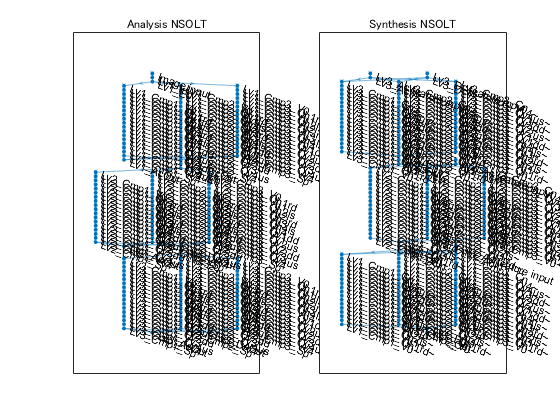

import saivdr.dcnn.*
load ./data/nsoltdictionary_rgb.mat
analysislgraph = layerGraph(analysisnet);
synthesislgraph = layerGraph(synthesisnet);

figure(4)
subplot(1,2,1)
plot(analysislgraph)
title('Analysis NSOLT')
subplot(1,2,2)
plot(synthesislgraph)
title('Synthesis NSOLT')

Reshape the atoms into atomic images

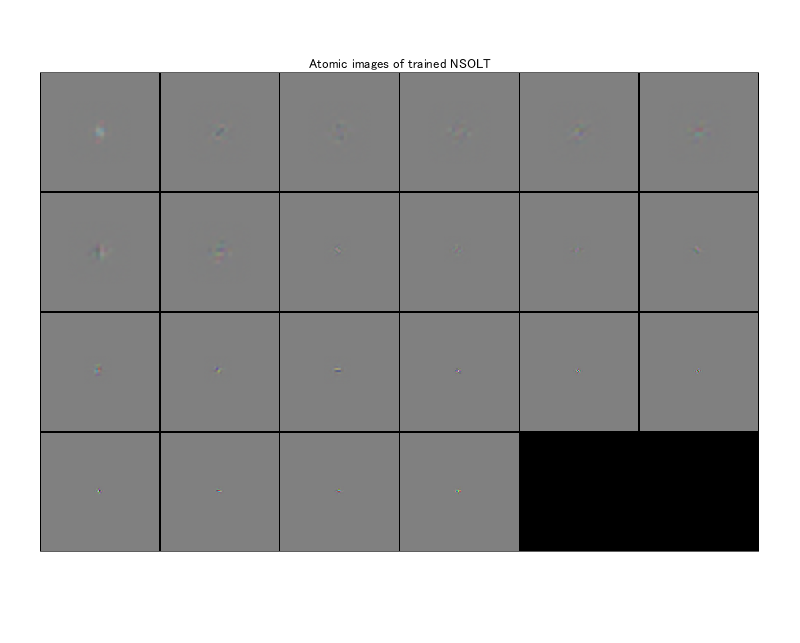

figure(5)
atomicimshow(synthesisnet)
title('Atomic images of trained NSOLT')

nLevels = extractnumlevels(analysisnet);
decFactor = extractdecfactor(analysisnet);
nChannels = extractnumchannels(analysisnet);
szOrg = size(u);

% Assemble analyzer
analysislgraph4predict = analysislgraph;
analysislgraph4predict = analysislgraph4predict.replaceLayer('Image input',...
    imageInputLayer(szOrg,'Name','Image imput','Normalization','none'));
for iLayer = 1:height(analysislgraph4predict.Layers)
    layer = analysislgraph4predict.Layers(iLayer);
    if contains(layer.Name,"Lv"+nLevels+"_DcOut") || ...
            ~isempty(regexp(layer.Name,'^Lv\d+_AcOut','once'))
        analysislgraph4predict = analysislgraph4predict.addLayers(...
            regressionLayer('Name',[layer.Name '_Reg']));        
        analysislgraph4predict = analysislgraph4predict.connectLayers(layer.Name,...
            [layer.Name '_Reg']);
    end
end
analysisnet4predict = assembleNetwork(analysislgraph4predict);

% Assemble synthesizer
synthesislgraph4predict = synthesislgraph;
synthesislgraph4predict = synthesislgraph4predict.replaceLayer('Lv1_Out',...
    regressionLayer('Name','Lv1_Out'));
for iLayer = 1:height(synthesislgraph4predict.Layers)
    layer = synthesislgraph4predict.Layers(iLayer);
    if contains(layer.Name,'Ac feature input')
        iLv = str2double(layer.Name(3));
        sbSize = szOrg(1:2).*(decFactor.^(-iLv));
        newlayer = ...
            imageInputLayer([sbSize szOrg(3)*(sum(nChannels)-1)],'Name',layer.Name,'Normalization','none');
        synthesislgraph4predict = synthesislgraph4predict.replaceLayer(...
            layer.Name,newlayer);
    elseif contains(layer.Name,sprintf('Lv%0d_Dc feature input',nLevels))
        iLv = str2double(layer.Name(3));
        sbSize = szOrg(1:2).*(decFactor.^(-iLv));
        newlayer = ...
            imageInputLayer([sbSize szOrg(3)],'Name',layer.Name,'Normalization','none');
        synthesislgraph4predict = synthesislgraph4predict.replaceLayer(...
            layer.Name,newlayer);
    end
end
synthesisnet4predict = assembleNetwork(synthesislgraph4predict);  

Confirmation of perfect reconstruction (adjoint relation)

x = rand(szOrg,'single');
[s{1:nLevels+1}] = analysisnet4predict.predict(x);
y = synthesisnet4predict.predict(s{1:nLevels+1});
display("MSE: " + num2str(mse(x,y)))

    "MSE: 6.8922e-15  5.3499e-15  6.3434e-15"



#### Adjoint operator of the measurement process

% Adjoint process P.'
upsample2 = @(x,m) ipermute(upsample(permute(upsample(x,m),[2 1 3]),m),[2 1 3]);
adjproc = @(x) imfilter(upsample2(x,2),h,'corr','circ');


## Execution of proximal-gradient method (ISTA)

- "synthesisnet" and "analysisnet" are objects of "dlnetwork."

- "dlnetwork" takes "dlarray."

- Function "extractdata" is used for extracting ordinary array data from "dlarray."  

% Parameter settings
lambda = 0.0004;
gamma = 2./(beta+1e-2);
nIters = 50;
isDcSkip = true;

% Initalization
z = zeros(szOrg,'like',u);
[coefs{1:nLevels+1}] = analysisnet4predict.predict(z);

% profile on
for itr = 1:nIters
    x = linproc(synthesisnet4predict.predict(coefs{1:nLevels+1}));
    [g{1:nLevels+1}] = analysisnet4predict.predict(adjproc(x-v));
    % Gradient descnet
    for iOutput = 1:nLevels+1
        coefs{iOutput} = coefs{iOutput}-gamma*g{iOutput};
        if ~isDcSkip || iOutput < nLevels+1 
            % ISTA for detail (w/o soft-thresholding for approximation components)
            coefs{iOutput} = wthresh(coefs{iOutput},'s',gamma*lambda);
        end
    end
end
% profile off
% profile viewer


% Reconstruction
r = synthesisnet4predict.predict(coefs{1:nLevels+1});

### Display the result

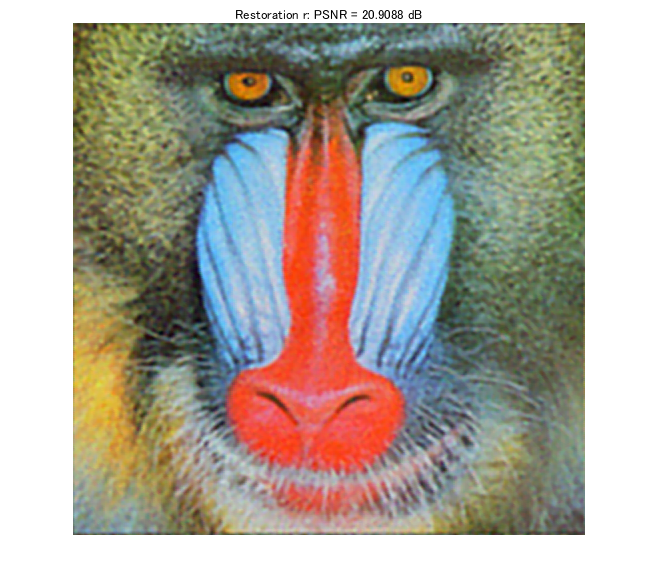

figure(6)
imshow(r)
title(['Restoration r: PSNR = ' num2str(psnr(u,r)) ' dB']);

function nLevels = extractnumlevels(nsoltnet)
import saivdr.dcnn.*

% Extraction of information
expidctlayer = '^Lv\d+_E0~?$';
nLevels = 0;
nLayers = height(nsoltnet.Layers);
for iLayer = 1:nLayers
    layer = nsoltnet.Layers(iLayer);
    if ~isempty(regexp(layer.Name,expidctlayer,'once'))
        nLevels = nLevels + 1;
    end
end
end

function decFactor = extractdecfactor(nsoltnet)
import saivdr.dcnn.*

% Extraction of information
expfinallayer = '^Lv1_Cmp1+_V0~?$';
nLayers = height(nsoltnet.Layers);
for iLayer = 1:nLayers
    layer = nsoltnet.Layers(iLayer);
    if ~isempty(regexp(layer.Name,expfinallayer,'once'))
        decFactor = layer.DecimationFactor;
    end
end
end

function nChannels = extractnumchannels(nsoltnet)
import saivdr.dcnn.*

% Extraction of information
expfinallayer = '^Lv1_Cmp1+_V0~?$';
nLayers = height(nsoltnet.Layers);
for iLayer = 1:nLayers
    layer = nsoltnet.Layers(iLayer);
    if ~isempty(regexp(layer.Name,expfinallayer,'once'))
        nChannels = layer.NumberOfChannels;
    end
end
end